# ASSIGNMENT 3

## AYUSH MISHRA

## 250253

## **Problem 1: Lead Compensator for Speed Improvement**

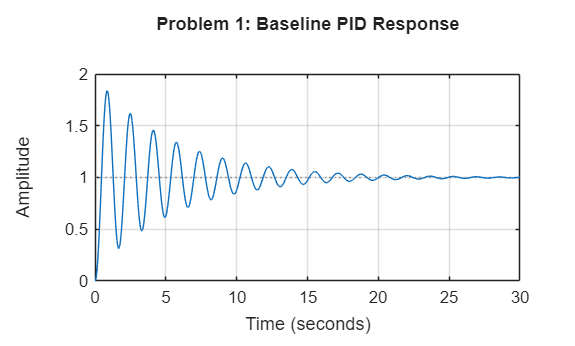

clc; clear; close all;

% ----- Problem 1 Plant -----
G1_num = 20;
G1_den = conv([1 0], conv([1 2], [1 5]));
G1 = tf(G1_num, G1_den);
% PID controller for Problem 1
Kp1 = 5;
Ki1 = 2;
Kd1 = 0.5;

C1_pid = pid(Kp1, Ki1, Kd1);

% Closed-loop system
T1_pid = feedback(C1_pid * G1, 1);

figure;
step(T1_pid);
grid on;
title('Problem 1: Baseline PID Response');


info_T1_pid = stepinfo(T1_pid)

info_T1_pid = struct with fields:
         RiseTime: 0.2931
    TransientTime: 21.2755
     SettlingTime: 21.2755
      SettlingMin: 0.3142
      SettlingMax: 1.8390
        Overshoot: 83.9015
       Undershoot: 0
             Peak: 1.8390
         PeakTime: 0.8607


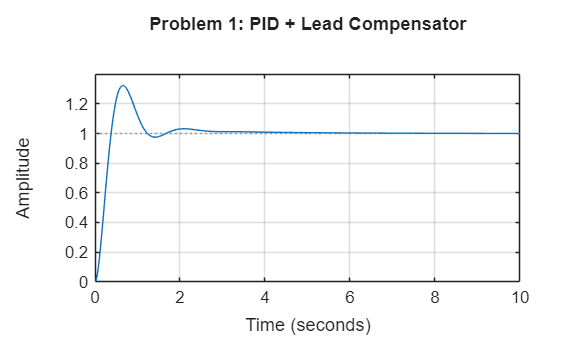


% Lead compensator
z1 = 3;
p1 = 15;
Kc1 = 4;

C1_lead = Kc1 * tf([1 z1], [1 p1]);

% Combined controller
C1_total = C1_pid * C1_lead;

T1_lead = feedback(C1_total * G1, 1);

figure;
step(T1_lead);
grid on;
title('Problem 1: PID + Lead Compensator');


info_T1_lead = stepinfo(T1_lead)

info_T1_lead = struct with fields:
         RiseTime: 0.2611
    TransientTime: 2.5050
     SettlingTime: 2.5050
      SettlingMin: 0.9468
      SettlingMax: 1.3239
        Overshoot: 32.3942
       Undershoot: 0
             Peak: 1.3239
         PeakTime: 0.6514


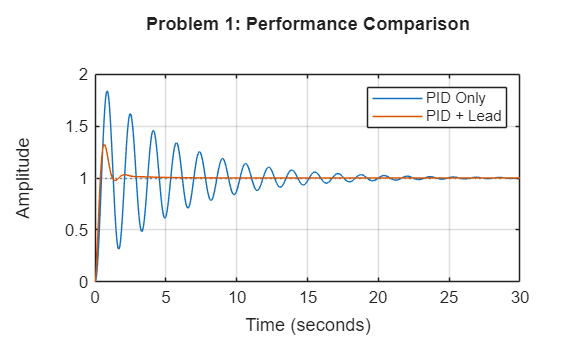


%Performance Comparison
figure;
step(T1_pid, T1_lead);
grid on;
legend('PID Only', 'PID + Lead');
title('Problem 1: Performance Comparison');

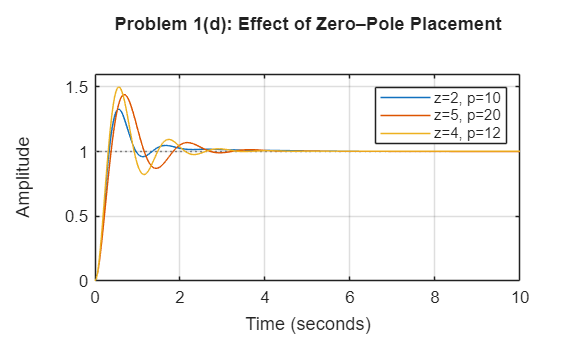



configs = [2 10; 
           5 20; 
           4 12];

figure; hold on;

for i = 1:size(configs,1)
    z_test = configs(i,1);
    p_test = configs(i,2);

    C_lead_test = Kc1 * tf([1 z_test], [1 p_test]);
    T_test = feedback(C1_pid * C_lead_test * G1, 1);

    step(T_test);
end

grid on;
legend('z=2, p=10','z=5, p=20','z=4, p=12');
title('Problem 1(d): Effect of Zero–Pole Placement');

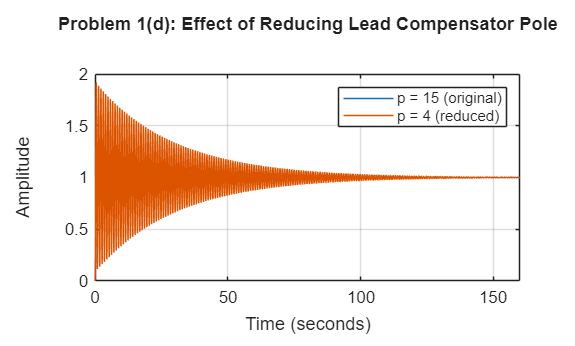


% Fixed zero
z_fixed = 3;

% Original and reduced pole values
p_original = 15;
p_reduced  = 4;

C_lead_original = Kc1 * tf([1 z_fixed], [1 p_original]);
C_lead_reduced  = Kc1 * tf([1 z_fixed], [1 p_reduced]);

T_original = feedback(C1_pid * C_lead_original * G1, 1);
T_reduced  = feedback(C1_pid * C_lead_reduced  * G1, 1);

figure;
step(T_original, T_reduced);
grid on;
legend('p = 15 (original)','p = 4 (reduced)');
title('Problem 1(d): Effect of Reducing Lead Compensator Pole');

**OBSERVATIONS**

**Reducing the pole value:**

- Decreases the separation between zero and pole

- Reduces phase lead

- Slows down the transient response

**Larger pole values:**

- Provide stronger phase lead

- Improve rise time and settling time

**Excessively reducing the pole:**

- Makes the compensator behave closer to a proportional controller

- Loses the benefit of lead compensation

**Conclusion for Problem 1(d)**

- Zero–pole separation determines speed improvement

- Larger separation → faster response

- Reducing the pole value:

- Improves stability margin

- Sacrifices speed

- Proper pole placement is a trade-off between speed and robustness

## Problem 2: Lag Compensator for Steady-State Accuracy

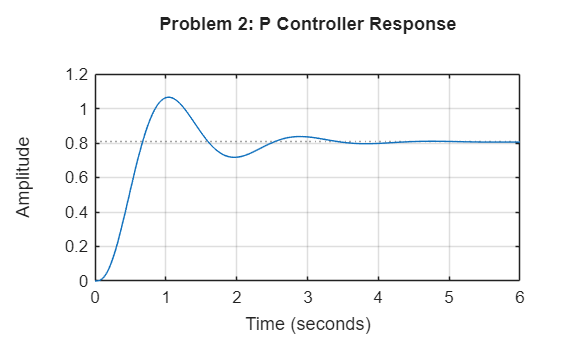

% ----- Problem 2 Plant -----
G2 = tf(50, conv([1 1], conv([1 3], [1 8])));
Kp2 = 2;

T2_P = feedback(Kp2 * G2, 1);

figure;
step(T2_P);
grid on;
title('Problem 2: P Controller Response');


yfinal_P = dcgain(T2_P);
ess_P = abs(1 - yfinal_P)

ess_P = 0.1935

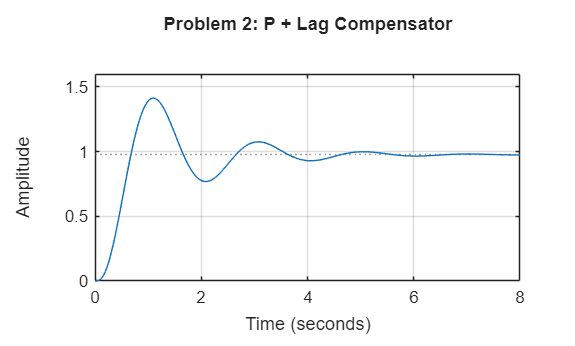


z2 = 1;
p2 = 0.1;

C2_lag = tf([1 z2], [1 p2]);

C2_total = Kp2 * C2_lag;

T2_lag = feedback(C2_total * G2, 1);

figure;
step(T2_lag);
grid on;
title('Problem 2: P + Lag Compensator');


yfinal_lag = dcgain(T2_lag);
ess_lag = abs(1 - yfinal_lag)

ess_lag = 0.0234


error_reduction_percent = ((ess_P - ess_lag) / ess_P) * 100

error_reduction_percent = 87.8906

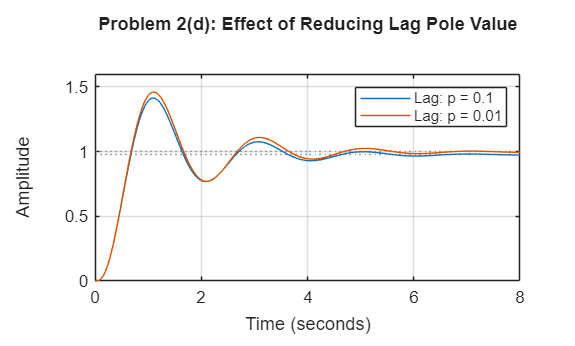


% Reduced pole value for trade-off analysis
p2_reduced = 0.01;

C2_lag_reduced = tf([1 z2], [1 p2_reduced]);

% Closed-loop system with reduced pole
T2_lag_reduced = feedback(Kp2 * C2_lag_reduced * G2, 1);

% Step response comparison
figure;
step(T2_lag, T2_lag_reduced);
grid on;
legend('Lag: p = 0.1','Lag: p = 0.01');
title('Problem 2(d): Effect of Reducing Lag Pole Value');

ess_lag_reduced = abs(1 - dcgain(T2_lag_reduced))

ess_lag_reduced = 0.0024

## Observations

- Reducing the pole value from 0.1 → 0.01:

- Further reduces steady-state error

- Increases settling time

- Makes the response more sluggish

## Conclusion (Trade-off Explanation)

- Lag compensators improve accuracy by increasing low-frequency gain

- Moving the pole closer to the origin:

- Improves accuracy

- Degrades speed

- This demonstrates the fundamental control trade-off:

                         Accuracy INVERSELY PROPORTIONAL TO Speed

## Problem 3: Feedforward + Feedback Control

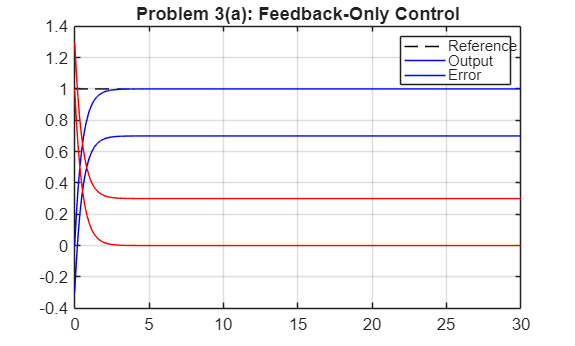

% ----- Problem 3 Plant -----
G3 = tf(1, [1 0.5]);
% PI controller parameters
Kp3 = 2;
Ki3 = 1;

C3_PI = pid(Kp3, Ki3);
t = 0:0.01:30;
dt = 0.01;

r = ones(size(t));
d = 0.3 * (t >= 5);

% Closed-loop feedback system
T3_fb = feedback(C3_PI * G3, 1);

% Output with disturbance
y_fb = lsim(T3_fb, r, t) - d;

% Error signal
e_fb = r - y_fb;
figure;
plot(t, r, 'k--', t, y_fb, 'b', t, e_fb, 'r');
grid on;
legend('Reference','Output','Error');
title('Problem 3(a): Feedback-Only Control');

max_error_fb = max(abs(e_fb(t >= 5)))

max_error_fb = 4.5400e-05

% Indices after disturbance starts (t >= 5)
idx_after_dist = find(t >= 5);

% Find recovery index AFTER disturbance
idx_recovery_fb = idx_after_dist( ...
    find(abs(e_fb(idx_after_dist)) < 0.02, 1, 'first') ...
);

if isempty(idx_recovery_fb)
    recovery_time_fb = NaN;   % Did not recover within simulation time
else
    recovery_time_fb = t(idx_recovery_fb);
end


**Explanation**

- Feedback reacts after disturbance affects output

- Large transient error appears at t=5st = 5st=5s

- Recovery is slow due to reactive nature

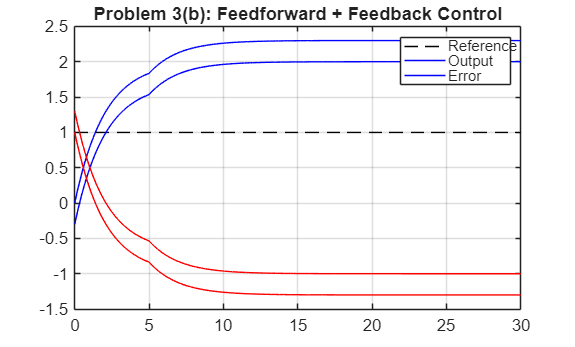

Kff = 1 / dcgain(G3);
u_ff = Kff * d;

% Feedforward + feedback output
y_ff = lsim(G3, r + u_ff, t) - d;

% Error signal
e_ff = r - y_ff;
figure;
plot(t, r, 'k--', t, y_ff, 'b', t, e_ff, 'r');
grid on;
legend('Reference','Output','Error');
title('Problem 3(b): Feedforward + Feedback Control');

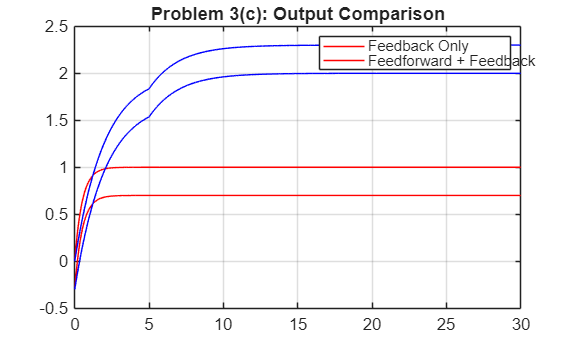

figure;
plot(t, y_fb, 'r', t, y_ff, 'b');
grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Problem 3(c): Output Comparison');

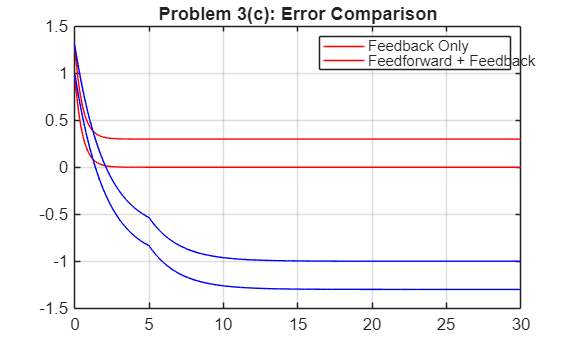


figure;
plot(t, e_fb, 'r', t, e_ff, 'b');
grid on;
legend('Feedback Only','Feedforward + Feedback');
title('Problem 3(c): Error Comparison');

**Explanation**

- Feedforward cancels disturbance **before it affects output**

- Feedback fine-tunes residual error

- Combined control yields superior disturbance rejection

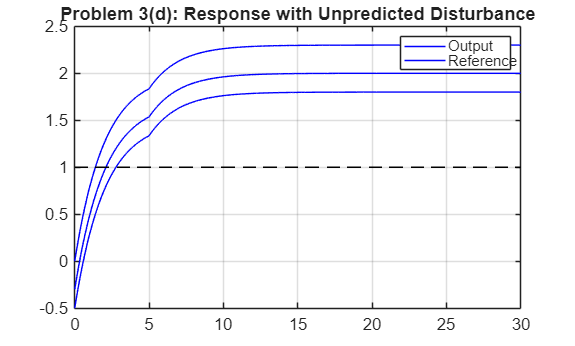

d_unpred = 0.2 * (t >= 15);

% Total disturbance
d_total = d + d_unpred;

% Output with unpredicted disturbance
y_unpred = lsim(G3, r + u_ff, t) - d_total;

e_unpred = r - y_unpred;
figure;
plot(t, y_unpred, 'b', t, r, 'k--');
grid on;
legend('Output','Reference');
title('Problem 3(d): Response with Unpredicted Disturbance');

**Discussion**

- Feedforward **cannot handle unknown disturbances**

- Feedback automatically corrects the error

- Demonstrates **complementary nature**:

- Feedforward → proactive

- Feedback → robust

## Problem 4: Simple MIMO System Control

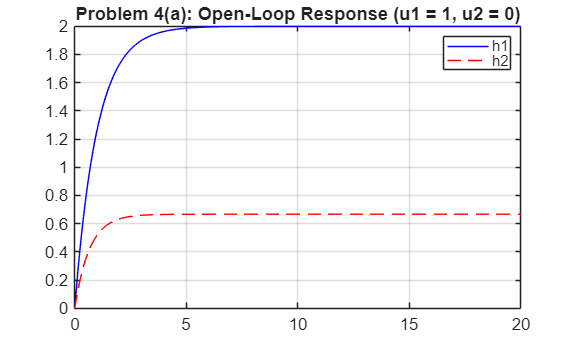

% ----- Problem 4: MIMO Plant -----
G11 = tf(2,[1 1]);      % u1 -> h1
G12 = tf(0.5,[1 2]);    % u2 -> h1 (coupling)
G21 = tf(1,[1 1.5]);    % u1 -> h2 (coupling)
G22 = tf(3,[1 1]);      % u2 -> h2

G4 = [G11 G12;
      G21 G22];
t = 0:0.05:20;

u = [ones(size(t)); zeros(size(t))]';
[y,~] = lsim(G4, u, t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
grid on;
legend('h1','h2');
title('Problem 4(a): Open-Loop Response (u1 = 1, u2 = 0)');

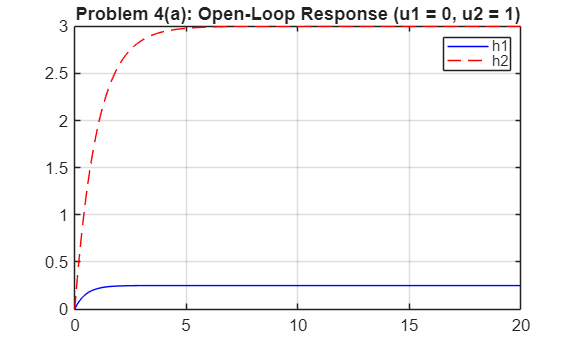

u = [zeros(size(t)); ones(size(t))]';
[y,~] = lsim(G4, u, t);

figure;
plot(t, y(:,1), 'b', t, y(:,2), 'r--');
grid on;
legend('h1','h2');
title('Problem 4(a): Open-Loop Response (u1 = 0, u2 = 1)');

**Explanation**

- Each input affects **both outputs**

- This confirms **cross-coupling**

- Independent SISO thinking fails in MIMO systems

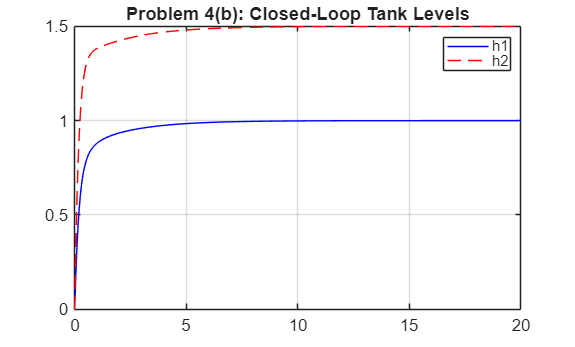

dt = 0.05;
t = 0:dt:20;

G4d = c2d(G4, dt);     % Discrete-time MIMO system
G4d_ss = ss(G4d);      % Convert to state-space
Ad = G4d_ss.A;
Bd = G4d_ss.B;
Cd = G4d_ss.C;
Dd = G4d_ss.D;

x = zeros(size(Ad,1),1);   % State vector
r1 = ones(size(t));
r2 = 1.5 * ones(size(t));

h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0;
e2_int = 0;
for k = 2:length(t)

    % Errors
    e1 = r1(k) - h1(k-1);
    e2 = r2(k) - h2(k-1);

    % PI controllers
    u1(k) = 1.5*e1 + 0.8*e1_int;
    u2(k) = 1.2*e2 + 0.6*e2_int;

    % Integral update
    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    % State update
    x = Ad*x + Bd*[u1(k); u2(k)];

    % Output equation
    y = Cd*x + Dd*[u1(k); u2(k)];

    h1(k) = y(1);
    h2(k) = y(2);
end
figure;
plot(t, h1, 'b', t, h2, 'r--');
grid on;
legend('h1','h2');
title('Problem 4(b): Closed-Loop Tank Levels');

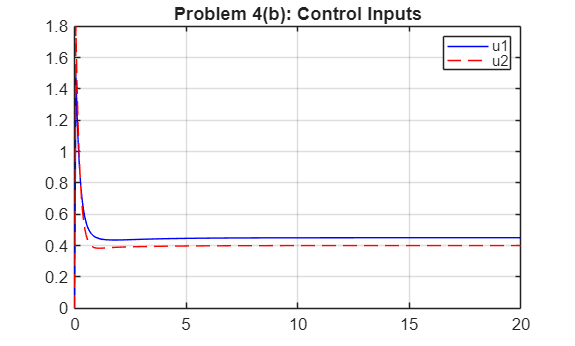


figure;
plot(t, u1, 'b', t, u2, 'r--');
grid on;
legend('u1','u2');
title('Problem 4(b): Control Inputs');

final_h1 = h1(end)

final_h1 = 1.0000

final_h2 = h2(end)

final_h2 = 1.5000

**Discussion**

- Controllers interfere due to coupling

- Adjusting one input disturbs both outputs

- Overshoot and interaction are unavoidable with decentralized control

- Independent PI controllers ignore cross-terms

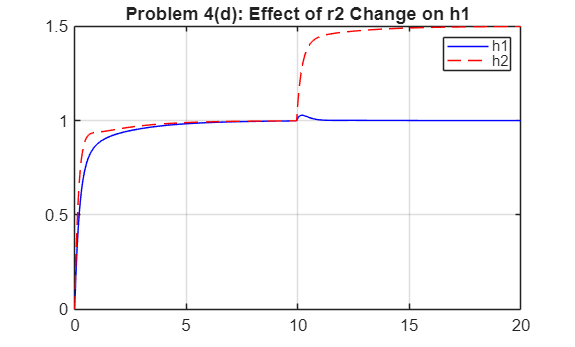

r2 = ones(size(t));
r2(t >= 10) = 1.5;

% Reset states and integrators
x = zeros(size(Ad,1),1);
e1_int = 0;
e2_int = 0;
h1(:) = 0;
h2(:) = 0;
u1(:) = 0;
u2(:) = 0;

for k = 2:length(t)

    e1 = r1(k) - h1(k-1);
    e2 = r2(k) - h2(k-1);

    u1(k) = 1.5*e1 + 0.8*e1_int;
    u2(k) = 1.2*e2 + 0.6*e2_int;

    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    x = Ad*x + Bd*[u1(k); u2(k)];
    y = Cd*x + Dd*[u1(k); u2(k)];

    h1(k) = y(1);
    h2(k) = y(2);
end
figure;
plot(t, h1, 'b', t, h2, 'r--');
grid on;
legend('h1','h2');
title('Problem 4(d): Effect of r2 Change on h1');

**Explanation**

- Change in r2r_2r2� disturbs h1h_1h1�

- Demonstrates strong interaction

- Highlights difficulty of MIMO control

#### Why MIMO Systems Are Harder Than SISO

- Multiple inputs affect multiple outputs

- Controllers interact unintentionally

- Stability and tuning are multivariable

- Advanced control methods are required

#### Suggested Improvements

- Decoupling control

- State-space MIMO design

- LQR / MPC

- Model-based compensation

# Summary Questions

1. When would you choose a lead compensator over increasing PID gains?

A lead compensator is chosen when faster transient response and improved stability margins are required but increasing PID gains would cause excessive overshoot, noise amplification, or instability.

Lead compensators increase phase margin and speed up the system without aggressively raising controller gains.

**2. What are the main advantages and limitations of lag compensators?**

**Advantages:**

Lag compensators improve steady-state accuracy by increasing low-frequency gain without significantly affecting system stability.

**Limitations:**

They slow down the transient response, increase settling time, and are not suitable when fast system response is required.**3. Why is feedforward control called “proactive” compared to feedback?**

Feedforward control is called proactive because it compensates for known disturbances before they affect the system output.

In contrast, feedback control reacts only after an error has already occurred.

**4. What makes MIMO systems more difficult to control than SISO systems?**

MIMO systems are more difficult to control because multiple inputs affect multiple outputs, causing interaction and coupling between control loops.

This interaction makes independent tuning ineffective and often requires advanced multivariable control strategies.